# Initialisation


clc; 
clear; 
close all;

## Paramètres généraux

Ns = 5000;       % Nombre de symboles
Ds = 1e6;        % Débit symbole (1 Msymboles/s)
Fse = 4;         % Facteur de suréchantillonnage
Fe = Ds*Fse;     % Fréquence d'échantillonnage (4 MHz)
rolloff = 0.35;  % Rolloff pour le RRC
SPAN = 8;        % Nombre de périodes symboliques pour le RRC

## Développement du canal

Generation des bits QPSK

bits = randi([0 1], 2*Ns, 1); 
% mapping de gray
symI = 1-2*bits(1:2:end);
symQ = 1-2*bits(2:2:end);
symboles = (symI + 1j*symQ)/sqrt(2);  % Normalisation d'énergie = 1

Filtre d'émission RRC

% Filtre en racine de cosinus surélevé : on utilise rcosdesign
h_rrc = rcosdesign(rolloff, SPAN, Fse, 'sqrt');

% Suréchantillonnage
x_up = upsample(symboles, Fse);

% Convolution avec le filtre RRC (émission)
x_emis = conv(x_up, h_rrc, 'full');


Définition des cas de canal à tester

% Format {alpha_ch, d_ch, phi_ch}
canaux = {
    {1.0, 1, 0},      % Cas 1
    {1.0, 4, 0},      % Cas 2
    {1.0, 1, pi/4},   % Cas 3
    {0.5, 1, 0},      % Cas 4
    {0.5, 4, 0}       % Cas 5
};


Boucle sur les différents cas de canal

for cas_num = 1:length(canaux)
    
    % Récupération des paramètres pour ce cas
    alpha_ch = canaux{cas_num}{1};
    d_ch     = canaux{cas_num}{2};
    phi_ch   = canaux{cas_num}{3};
    
    % Construction du canal (et optionnellement, affichage)
    h_canal = create_canal(alpha_ch, d_ch, phi_ch);
    
    % On peut visualiser le canal si on veut
    % plot_canal(h_canal, cas_num);   % <-- décommenter si besoin

    %% 4.1) Convolution avec le canal
    y_canal = conv(x_emis, h_canal, 'full');
    
    %% 4.2) Filtre de réception RRC
    % On suppose gRx = h_rrc (même filtre)
    gRx = h_rrc; 
    y_rec = conv(y_canal, gRx, 'full');


    Échantillonnage

    % Le retard introduit par 2 filtres RRC vaut environ SPAN*Fse/2 + SPAN*Fse/2 = SPAN*Fse
    offset = SPAN * Fse;  
    nIdx   = offset + (0:Ns-1)*Fse;
    nIdx   = nIdx(nIdx <= length(y_rec));  % éviter dépassement
    y_sym  = y_rec(nIdx);
    

Affichage de la constellation pour ce cas

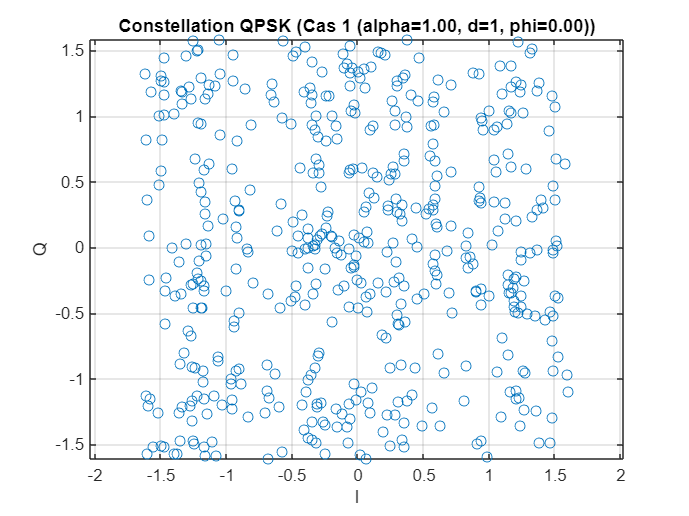

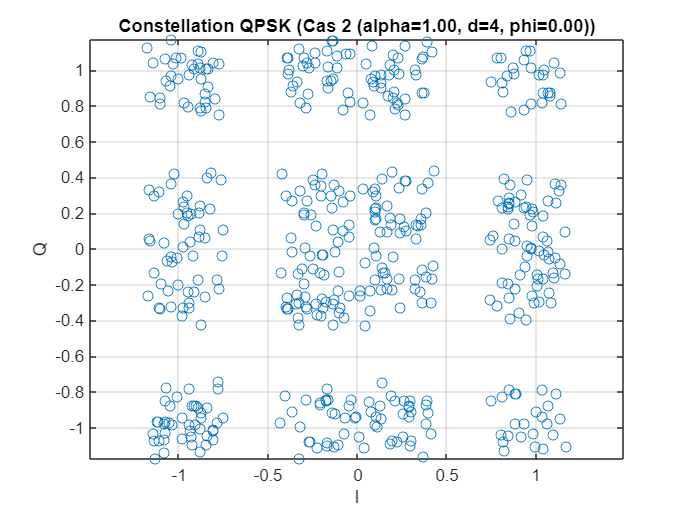

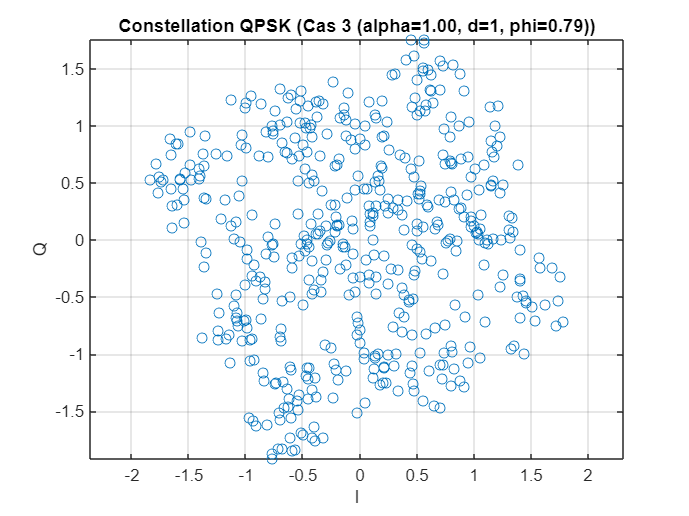

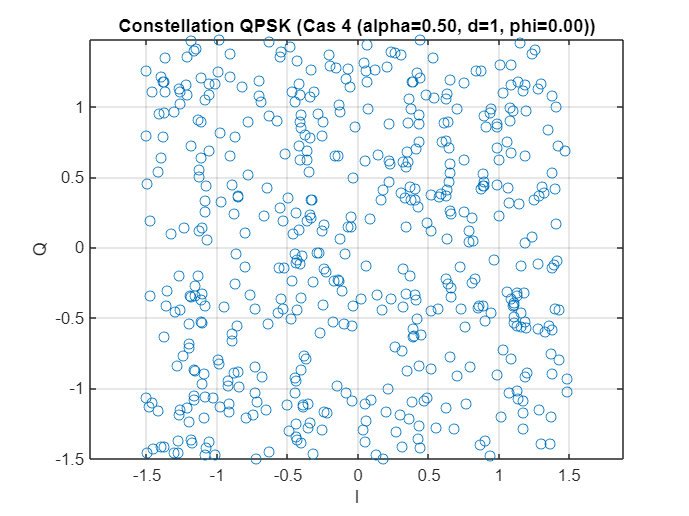

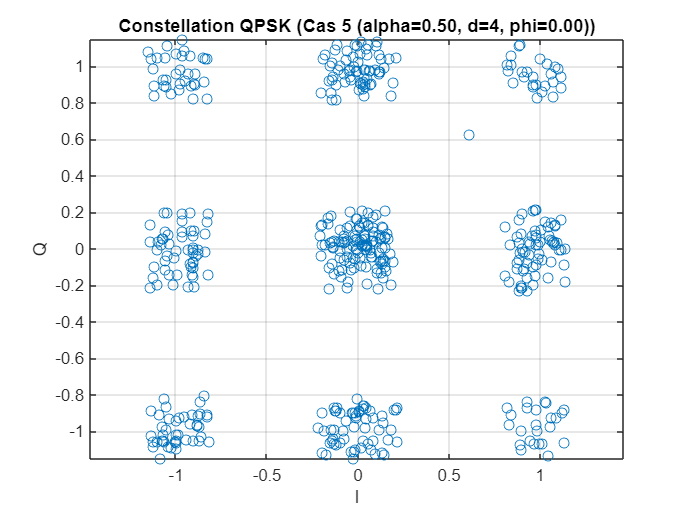

    figure;
    plot(real(y_sym(1:500)), imag(y_sym(1:500)), 'o');
    axis equal; grid on;
    xlabel('I'); ylabel('Q');
    titre = sprintf('Constellation QPSK (Cas %d (alpha=%.2f, d=%d, phi=%.2f))', ...
        cas_num, alpha_ch, d_ch, phi_ch);
    title(titre);
    

    if (alpha_ch == 1 && d_ch == 4) 
        y_1 = y_sym
    end
    if (alpha_ch == 0.5 && d_ch == 4)
        y_demi= y_sym
    end
end

y_1 =    0.4321 + 0.4414i
   0.1858 + 0.1782i
  -0.1865 - 0.1431i
   0.8602 + 0.7696i
   0.3929 + 1.1592i
  -0.8780 + 0.2447i
  -1.0019 - 0.2009i
  -1.0488 + 0.9153i
  -0.3196 + 0.3282i
   0.8131 - 0.1903i


y_demi =    0.6123 + 0.6256i
  -0.1040 - 0.1210i
  -0.0144 + 0.0528i
   0.9846 + 0.8302i
   0.0564 + 1.1228i
  -0.9185 - 0.0801i
  -0.9041 - 0.0192i
  -1.0563 + 1.0499i
  -0.0113 - 0.0559i
   0.8378 + 0.0228i


La forme des constellations est due aux interferences, vu qu'il y a plusieurs signaux ça crée des interférences qui vont "grossir" nos symbôles

plus le retard ( ou délai de propagation ) d est grand, plus le canal est sélectif en fréquence, donc plus il distord le signal.

impact de alpha et phi: ils déterminent la profondeur et la position des creux dans la réponse en fréquence, donc la sélectivité, et la rotation de la constellation en sortie. Un alpha élevé crée une constellation plus concentrée, tandis qu'un alpha faible cause une dispersion et un flux de symboles. Le décalage en phase phi déplace symplement le symbole dans une direction circulaire.

Ainsi sans égalisation, la constellation est dégradée. L’égaliseur (ZF, MMSE) permettra de retrouver 4 nuages QPSK compacts.

## Egalisation

P_values = [10, 30, 100];
% Initialisation des BER pour ZF et MMSE
BER_ZF = zeros(length(canaux), length(P_values));
BER_MMSE = zeros(length(canaux), length(P_values));

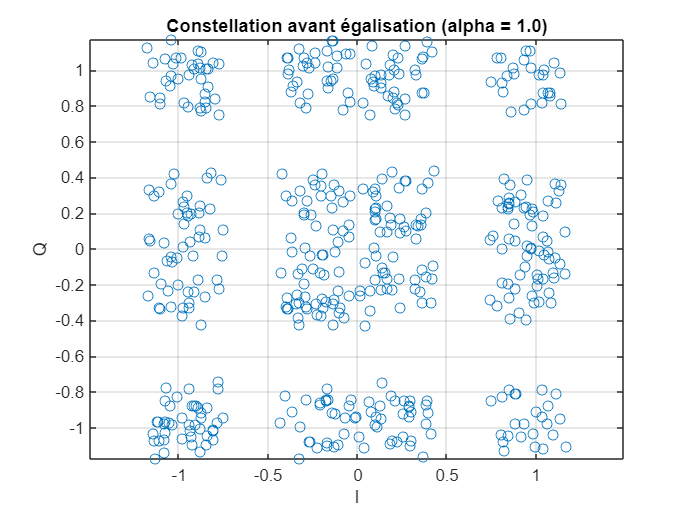

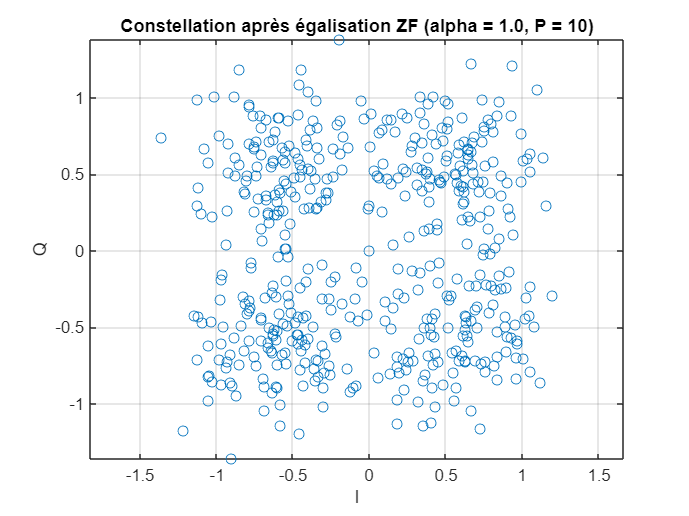

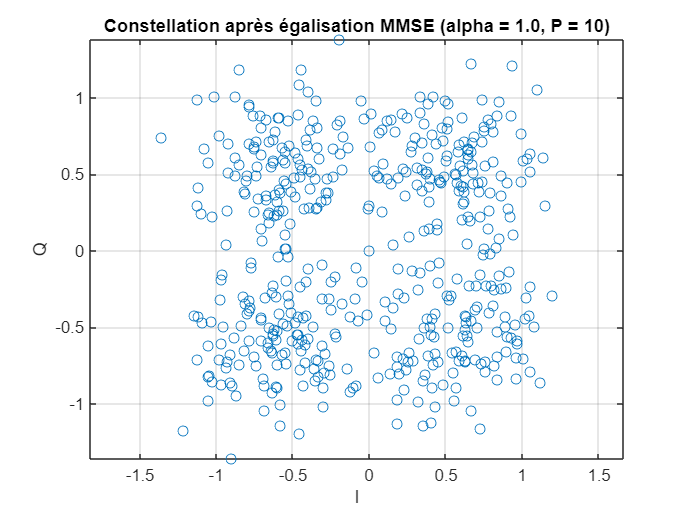

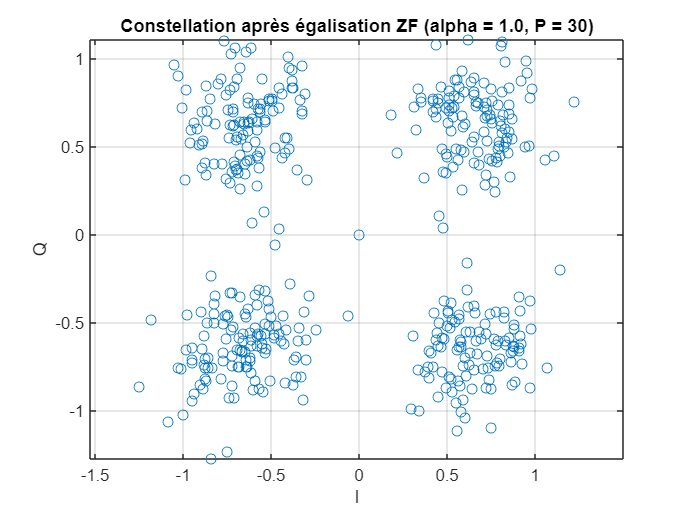

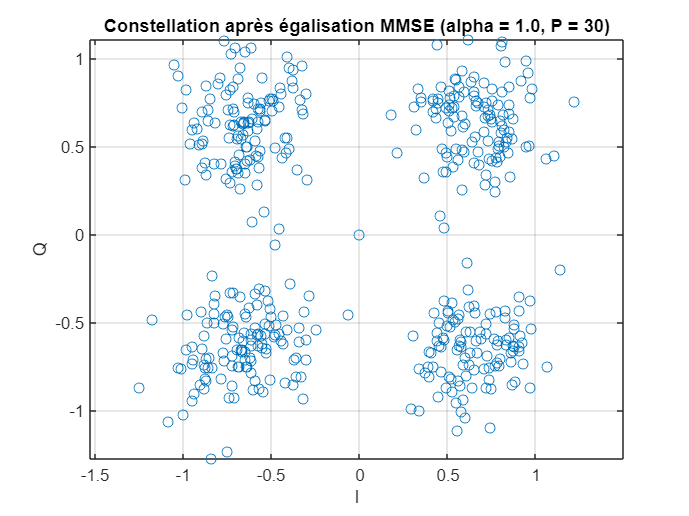

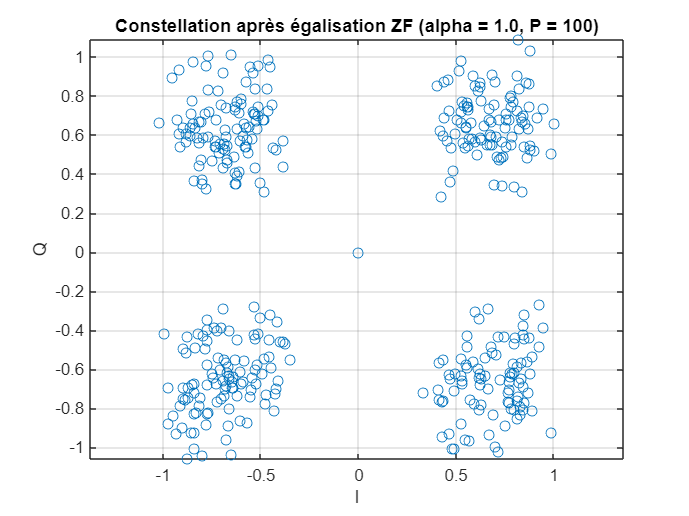

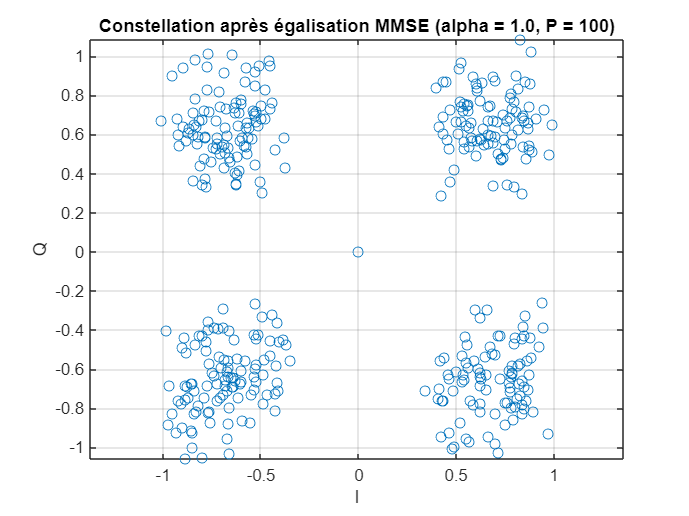

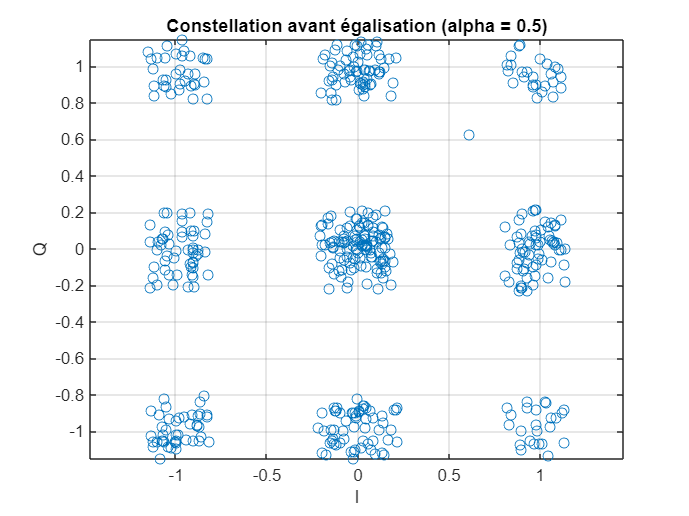

cas_alpha = { {y_1, 1}, {y_demi, 0.5} }; 
for i = 1:2 
    y_current = cas_alpha{i}{1}; 
    alpha = cas_alpha{i}{2}; % Constellation avant égalisation 
    figure; 
    plot(real(y_current(1:500)), imag(y_current(1:500)), 'o'); 
    axis equal; grid on; xlabel('I'); ylabel('Q'); 
    title(sprintf('Constellation avant égalisation (alpha = %.1f)', alpha)); 
        for p_idx = 1:length(P_values) 
            P = P_values(p_idx); % Égalisation ZF 
            [y_eq_ZF, ~] = equalize_ZF(y_current, symboles, P); 
            figure; 
            plot(real(y_eq_ZF(1:500)), imag(y_eq_ZF(1:500)), 'o'); 
            axis equal; grid on; xlabel('I'); ylabel('Q'); 
            title(sprintf('Constellation après égalisation ZF (alpha = %.1f, P = %d)', alpha, P)); 
            % Égalisation MMSE 
            [y_eq_MMSE, ~] = equalize_MMSE(y_current, symboles, P, 10); 
            figure;
            plot(real(y_eq_MMSE(1:500)), imag(y_eq_MMSE(1:500)), 'o'); 
            axis equal; grid on; xlabel('I'); ylabel('Q'); 
            title(sprintf('Constellation après égalisation MMSE (alpha = %.1f, P = %d)', alpha, P)); 
            % Calcul BER 
            BER_ZF(i, p_idx) = calcul_BER(y_eq_ZF, bits); 
            BER_MMSE(i, p_idx) = calcul_BER(y_eq_MMSE, bits); 
        end 
end 

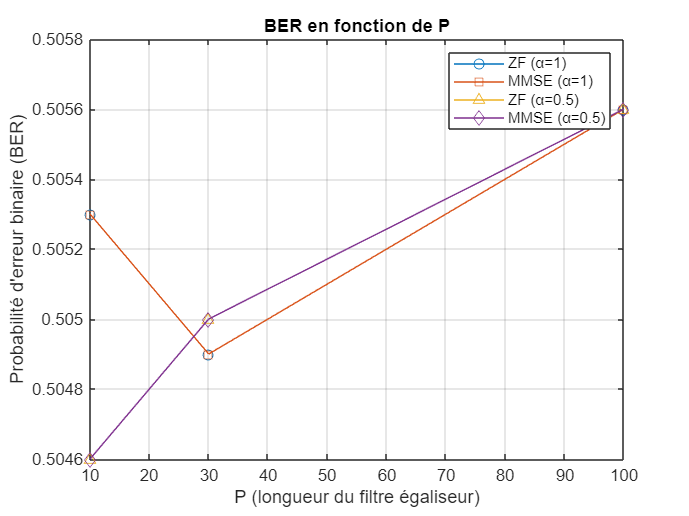


% Tracé des résultats 
figure; 
plot(P_values, BER_ZF(1,:), '-o', 'DisplayName', 'ZF (α=1)'); 
hold on; 
plot(P_values, BER_MMSE(1,:), '-s', 'DisplayName', 'MMSE (α=1)'); 
plot(P_values, BER_ZF(2,:), '-^', 'DisplayName', 'ZF (α=0.5)'); 
plot(P_values, BER_MMSE(2,:), '-d', 'DisplayName', 'MMSE (α=0.5)'); 
grid on; xlabel('P (longueur du filtre égaliseur)'); ylabel('Probabilité d''erreur binaire (BER)');
legend('show'); title('BER en fonction de P');

% Fonction de calcul de la BER
function ber = calcul_BER(y_eq, bits_orig)
    decisions = qpsk_demodulate(y_eq);
    bits_recu = reshape(de2bi(decisions, 2, 'left-msb')', [], 1);
    ber = sum(bits_recu ~= bits_orig) / length(bits_orig);
end

% Fonction de démodulation QPSK
function decisions = qpsk_demodulate(y_eq)
    decisions = zeros(size(y_eq));
    decisions(real(y_eq) >= 0 & imag(y_eq) >= 0) = 0; % 00
    decisions(real(y_eq) < 0 & imag(y_eq) >= 0)  = 1; % 01
    decisions(real(y_eq) < 0 & imag(y_eq) < 0)   = 2; % 10
    decisions(real(y_eq) >= 0 & imag(y_eq) < 0)  = 3; % 11
end
